# Presenting multiple signals

Copyright (C) [2020](#2020)  [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES

## Presenting ECG, PPG, PCG and SCG signals

We present ECG lead 1 signal, PPG signal measured at the finger, PCG signal collected by a microphone placed on the chest and accelerometer signal collected by an accelerometer placed on the chest

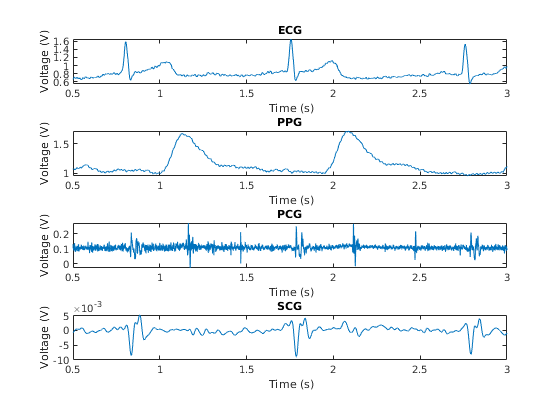


sig=readtable('sync_biomed_20201020_br12.csv');
fs=8008;
T=1/fs;
t=T:T:length(sig.ECG)*T;
subplot (411)
plot(t,sig.ECG)
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("ECG");
xlim([0.5,3])

subplot (412)
plot(t,sig.PPG)
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("PPG");
xlim([0.5,3])

subplot (413)
plot(t,sig.PCG)
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("PCG");
xlim([0.5,3])

% Filter SCG_z in the range of 0.47 Hz and 32 Hz using Wavelet
% decomposition
levelForReconstruction = [false, false, false, false, false, false, false, true, true, true, true, true, true, false, false, false, false];
% Perform the decomposition using modwt
wt = modwt(sig.SCG_Z, 'sym4', 16);
% Construct MRA matrix using modwtmra
mra = modwtmra(wt, 'sym4');
% Sum along selected multiresolution signals
a1 = sum(mra(levelForReconstruction,:),1);

subplot (414)
plot(t,a1)
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("SCG");
xlim([0.5,3])

## Presenting arterial central and peripheral blood pressure

We will present ECG lead 1 signal, PPG signal measured at the finger, arterial blood pressure and brachial oscillometric signal. Please note that the oscillometric signal is filtered. The signals and their units are:

Column 1: 'ECG      ' (V)

Column 2: 'Arterial central BP'  (mmHg)

Column 2: 'Arterial peritheral BP'  (mmHg)

The patient has cardiomyopathy.

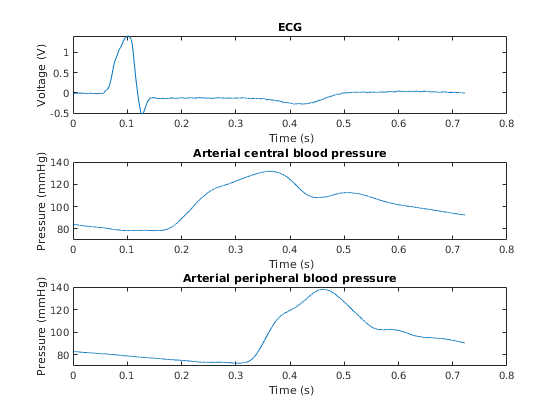

clear all
load('ecg_central_perBP.mat');
fs=4000;
T=1/fs;
t=T:T:length(b1(:,1))*T;
figure
subplot (311)
plot(t,b1(:,1))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("ECG");

subplot (312)
plot(t,b1(:,2))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Pressure (mmHg)', 'FontSize', 10)
title("Arterial central blood pressure");
ylim([70 140])

subplot (313)
plot(t,b1(:,3))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Pressure (mmHg)', 'FontSize', 10)
title("Arterial peripheral blood pressure");
ylim([70 140])

## Presenting ECG, PPG, Arterial and oscillometric signals

We will present ECG lead 1 signal, PPG signal measured at the finger, arterial blood pressure and brachial oscillometric signal. Please note that the oscillometric signal is filtered. The signals and their units are:

Column 1: 'ECG' (V)

Column 2: 'Arterial BP'  (mmHg)

Column 2: 'PPG' (V)

Column 4: 'Oscillometric total pressure'  (mmHg)

The patient has cardiomyopathy.

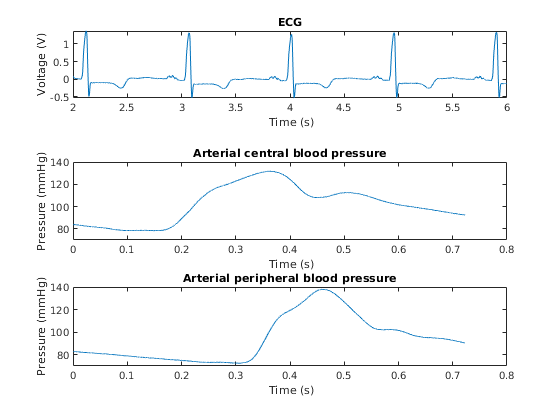

clear all
load('abp_ecg_ppg_osc.mat');
fs=4000;
T=1/fs;
t=T:T:length(a(:,1))*T;
subplot (411)
plot(t,a(:,1))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("ECG");
xlim([2,6])

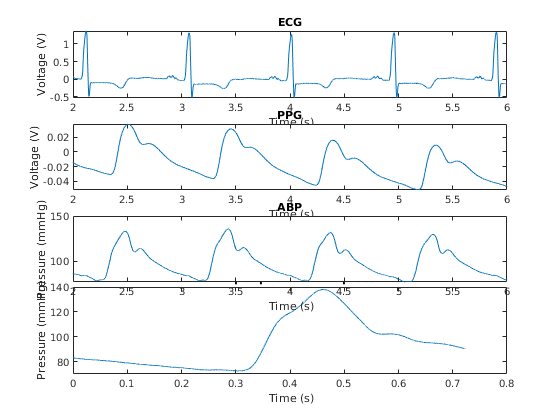


subplot (412)
plot(t,-a(:,3))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title("PPG");
xlim([2,6])

subplot (413)
plot(t,a(:,2))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Pressure (mmHg)', 'FontSize', 10)
title("ABP");
xlim([2,6])

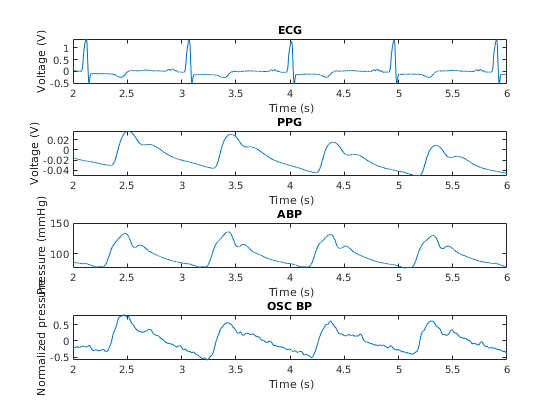


% Filter OSC in the range of 0.47 Hz and 16 Hz using Wavelet
% decomposition
levelForReconstruction = [false, false, false, false, false, false, true, true, true, true, true, true, false, false, false];
% Perform the decomposition using modwt
wt = modwt(a(:,4), 'sym4', 14);
% Construct MRA matrix using modwtmra
mra = modwtmra(wt, 'sym4');
% Sum along selected multiresolution signals
b1 = sum(mra(levelForReconstruction,:),1);

subplot (414)
plot(t,b1)
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Normalized pressure', 'FontSize', 10)
title("OSC BP");
xlim([2,6])

## Presenting ECG and SCG signals

We present ECG lead 1 signal and a signal collected by an accelerometer placed on the chest

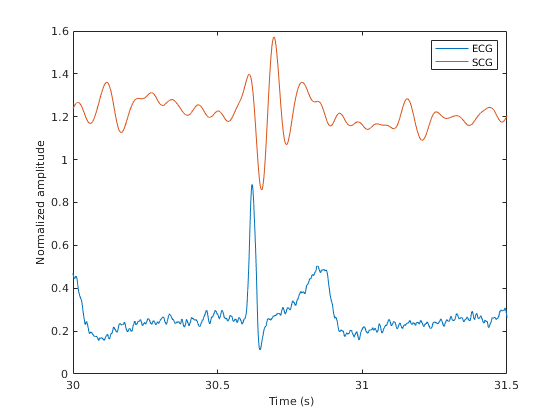


sig=readtable('sync_biomed_20201020_br12.csv');
figure
fs=8008;
T=1/fs;
t=T:T:length(sig.ECG)*T;

plot(t,rescale1(sig.ECG))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Normalized amplitude', 'FontSize', 10)




% Filter SCG_z in the range of 0.47 Hz and 16 Hz using Wavelet
% decomposition
levelForReconstruction = [false, false, false, false, false, false, false, false, true, true, true, true, true, false, false, false, false];
% Perform the decomposition using modwt
wt = modwt(sig.SCG_Z, 'sym4', 16);
% Construct MRA matrix using modwtmra
mra = modwtmra(wt, 'sym4');
% Sum along selected multiresolution signals
a1 = sum(mra(levelForReconstruction,:),1);

hold on
plot(t,rescale1(a1')+0.7)

legend("ECG","SCG");
xlim([30,31.5])